%Generacja systemu
r_min=-5;
r_max=5;
r=(r_min-r_max).*rand()+r_max;
b0=2*r;
r=(r_min-r_max).*rand()+r_max;
a0=2*r;
r=(r_min-r_max).*rand()+r_max;
a1=2*r;
r=(r_min-r_max).*rand()+r_max;
a2=2*r;
r=(r_min-r_max).*rand()+r_max;
a3=2*r;

a3=1;
a2=6;
a1=2;
a0=1;
b0=1;

L=[b0];
M=[a3 a2 a1 a0];
sys=tf(L,M)


sys =
 
            1
  ---------------------
  s^3 + 6 s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


[A, B, C, D]=tf2ss(L,M)

A =     -6    -2    -1
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0     0     1


D = 0

% norm(A,"fro")
% step(sys,0:0.1:30);

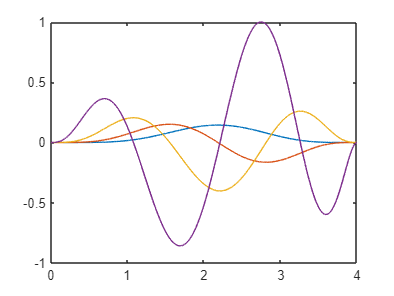

%funkcja phi /znormalizować
h=4;
step_size=0.001;
t=0:step_size:h-step_size;
N=6;
M=5;
% global phi phi_1 phi_2;
phi=(t.^N).*((h-t).^M);

% phi_1=diff(phi)/step_size;
phi_1=(N*t.^(N-1)).*((h-t).^M)-(M*t.^N).*(h-t).^(M-1);

% phi_2=diff(phi_1)/step_size;
phi_2=(M*t.^N).*((h-t).^(M-2)).*(M-1)-(2*M*N*t.^(N-1)).*((h-t).^(M-1))+(N*t.^(N-2).*((h-t).^M)*(N-1));

phi_3=3*M*N*t.^(N - 1).*(h - t).^(M - 2).*(M - 1) - M*t.^N.*(h - t).^(M - 3).*(M - 1).*(M - 2) - 3*M*N*t.^(N - 2).*(h - t).^(M - 1).*(N - 1) + N*t.^(N - 3).*(h - t).^M.*(N - 1).*(N - 2); 
phi=phi/max(abs(phi_3));

phi_1=phi_1/max(abs(phi_3));
phi_2=phi_2/max(abs(phi_3));
phi_3=phi_3/max(abs(phi_3));
plot(t,phi,t,phi_1,t,phi_2,t,phi_3)

trapz(t,phi,2)

ans = 0.2042

trapz(t,phi_1,2)

ans = 7.0698e-16

trapz(t,phi_2,2)

ans = -2.7113e-12

trapz(t,phi_3,2)

ans = 8.2663e-09

conv_size=length(phi);
T_iD=7/step_size;

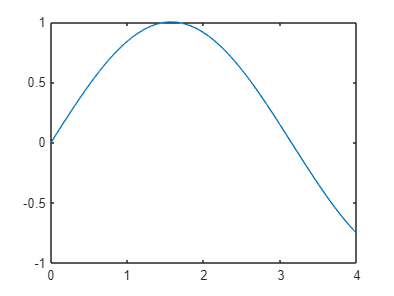

plot(t,sin(t))

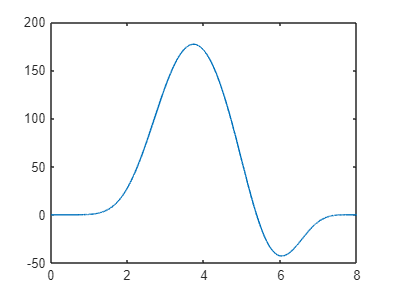

% plot(t,cumtrapz(t,sin(t)))
vec=0:step_size:(length(conv(sin(t),phi))-1)*step_size;
conv_plot=conv(sin(t),phi);
plot(vec,conv_plot)

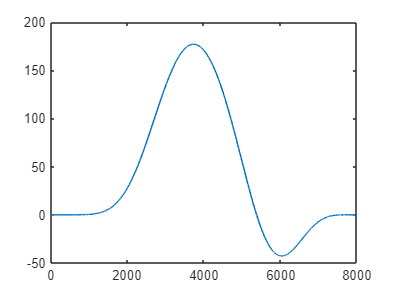


clear splot_1 splot_2
sinus=sin(t);
for j=1:length(sinus)+length(phi)-2
    clear splot_1
    if j<=length(sinus)        
        splot_1=sinus(1:j).*fliplr(phi(1:j));        
    else
        splot_1=sinus((j-length(sinus)):end).*fliplr(phi((j-length(sinus)):end));
    end
    splot_2(j)=trapz(step_size,splot_1,2);
end

SINUS=fft([sinus zeros(1,length(phi)-1)]);
PHI=fft([phi zeros(1,length(sinus)-1)]);
plot(ifft(SINUS.*PHI))

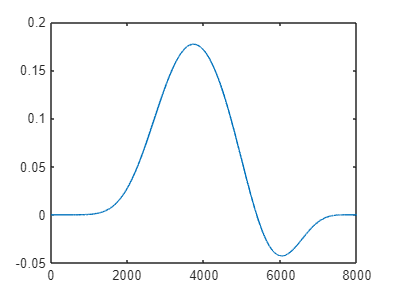


% plot(splot_1)
% xlim([0 400])
plot(splot_2)

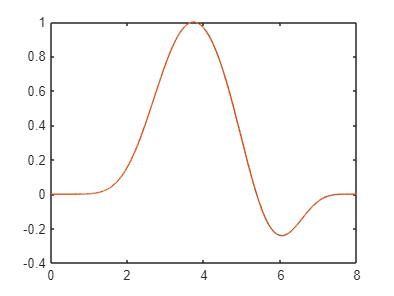

plot(vec(1:end-1),splot_2/max(splot_2),vec,conv_plot/max(conv_plot))

% xlim([0 400])
% plot(vec,conv(sin(t),phi_1))
% plot(cumtrapz(vec,conv(sin(t),phi),2))
% plot(vec,cumtrapz(vec,conv(sin(t),phi_1),2)*4.25,vec,conv(sin(t),phi))

%Regulator

Q=[0 0 0;
   0 0 0;
   0 0 10];
[K, S, poles]=lqr(A,B,Q,[0.5])

K =     0.8404    5.3955    3.5826


S =     0.4202    2.6977    1.7913
    2.6977   17.5027   12.6733
    1.7913   12.6733   15.9452


poles =   -0.5799 + 0.6858i
  -0.5799 - 0.6858i
  -5.6805 + 0.0000i


Ac=A-B*K;
% K=K/20000;

syms t N h M
phi_anal(t) = (t^N)*((h-t)^M);
phi_anal1(t)=diff(phi_anal,t)
phi_anal2(t)=diff(phi_anal1,t)
phi_anal3(t)=diff(phi_anal2,t)

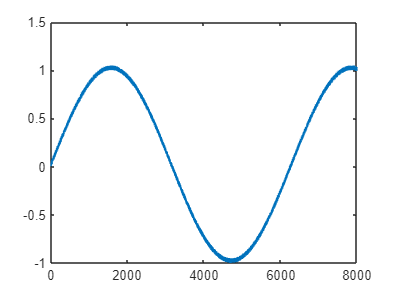

%simulate system
x0 = [0;0;0];             % Initial state (N=2)
Ns = 11/step_size; 	    % Number of sample times to simulate
u = sin(0:step_size:(T_iD-1)*step_size); % Input signal (an impulse at time 0)
y = zeros(T_iD,1);        % Preallocate output signal for n=0:Ns-1

% Perform the system simulation:
% x = x0;                % Set initial state
% x_p = x0;
% for n=1:Ns           % Iterate through time
%   y(n) = C*x_p + D*u(n); % Output for time n-1
%   x(:,end) = A*x_p + B*u(n);    % State transitions to time n
%   x = [x [0;0;0]];
%   x_p = trapz([0:step_size:(size(x,2)-2)*step_size],x(:,1:end-1),2);
% end
t=0:step_size:(length(y)-1)*step_size;
y=lsim(sys,u,t)+0.01*rand([length(u) 1]);
u=u+0.05*rand([1 length(u)]);
plot(u)

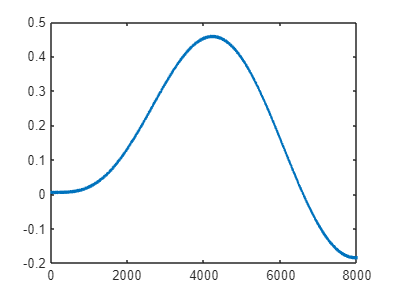

plot(y)

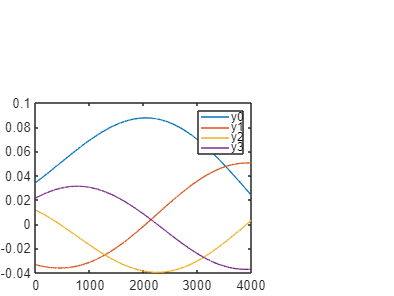

%evaluate method
t_=0:step_size:((conv_size-1)*step_size);
for n=1:T_iD-conv_size
    y0(n)=trapz(t_,(y(n:conv_size-1+n).*flipud(phi)'),1);
    y1(n)=trapz(t_,(y(n:conv_size-1+n).*flipud(phi_1)'),1);
    y2(n)=trapz(t_,(y(n:conv_size-1+n).*flipud(phi_2)'),1);
    y3(n)=trapz(t_,(y(n:conv_size-1+n).*flipud(phi_3)'),1);

    u0(n)=trapz(t_,(u(n:conv_size-1+n).*flipud(phi)),2);
    u1(n)=trapz(t_,(u(n:conv_size-1+n).*flipud(phi_1)),2);
    u2(n)=trapz(t_,(u(n:conv_size-1+n).*flipud(phi_2)),2);
    u3(n)=trapz(t_,(u(n:conv_size-1+n).*flipud(phi_3)),2);

    % y0(n)=trapz((y(n:conv_size-1+n).*flipud(phi)'),1);
    % y1(n)=trapz((y(n:conv_size-1+n).*flipud(phi_1)'),1);
    % y2(n)=trapz((y(n:conv_size-1+n).*flipud(phi_2)'),1);
    % y3(n)=trapz((y(n:conv_size-1+n).*flipud(phi_3)'),1);
    % 
    % u0(n)=trapz((u(n:conv_size-1+n).*flipud(phi)),2);
    % u1(n)=trapz((u(n:conv_size-1+n).*flipud(phi_1)),2);
    % u2(n)=trapz((u(n:conv_size-1+n).*flipud(phi_2)),2);
    % u3(n)=trapz((u(n:conv_size-1+n).*flipud(phi_3)),2);
end

% y0_=temp(length(phi):end-length(phi))*step_size;
% y0=y0/step_size;
% y1=y1/step_size;
% y2=y2/step_size;
% y3=y3/step_size;
% u0=u0/step_size;
% u1=u1/step_size;
% u2=u2/step_size;
% u3=u3/step_size;

% y0=fliplr(y0);
% y1=fliplr(y1);
% y2=fliplr(y2);
% y3=fliplr(y3);
% u0=fliplr(u0);
% u1=fliplr(u1);
% u2=fliplr(u2);
% u3=fliplr(u3);

% temp=conv(y,phi);
% y0=transpose(temp(length(phi):end-length(phi))*step_size);
% temp=conv(y,phi_1);
% y1=transpose(temp(length(phi):end-length(phi))*step_size);
% temp=conv(y,phi_2);
% y2=transpose(temp(length(phi):end-length(phi))*step_size);
% temp=conv(y,phi_3);
% y3=transpose(temp(length(phi):end-length(phi))*step_size);
% temp=conv(u,phi);
% u0=temp(length(phi):end-length(phi))*step_size;
% temp=conv(u,phi_1);
% u1=temp(length(phi):end-length(phi))*step_size;
% temp=conv(u,phi_2);
% u2=temp(length(phi):end-length(phi))*step_size;
% temp=conv(u,phi_3);
% u3=temp(length(phi):end-length(phi))*step_size;

% y0=transpose(conv(y,phi)*step_size);
% y1=transpose(conv(y,phi_1)*step_size);
% y2=transpose(conv(y,phi_2)*step_size);
% y3=transpose(conv(y,phi_3)*step_size);
% u0=conv(u,phi)*step_size;
% u1=conv(u,phi_1)*step_size;
% u2=conv(u,phi_2)*step_size;
% u3=conv(u,phi_3)*step_size;

plot(y0)
hold on
plot(y1)
plot(y2)
plot(y3)
legend('y0','y1','y2','y3')
hold off

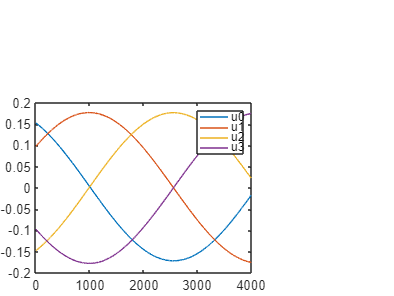

plot(u0)
hold on
plot(u1)
plot(u2)
plot(u3)
legend('u0','u1','u2','u3')
hold off

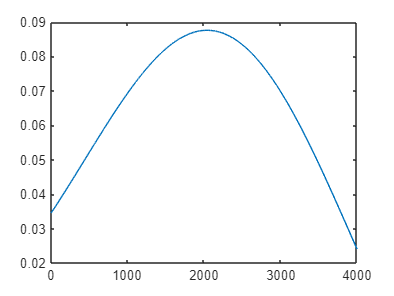

plot(y0)
hold on
% plot([zeros([length(phi) 1]); y0_; zeros([length(phi) 1])])
% plot(temp*step_size)
hold off

%macierz Gramma
t=0:step_size:((length(y0)-1)*step_size);
%         g11=trapz(t,y0.*y0,2);
%         g12=trapz(t,y0.*y1,2);
%         g13=trapz(t,y0.*y2,2);
%         g14=trapz(t,y0.*y3,2);
%         g15=trapz(t,y0.*u0,2);
%         g16=trapz(t,y0.*u1,2);
%         g17=trapz(t,y0.*u2,2);
%         g18=trapz(t,y0.*u3,2);
% 
% %         g21=trapz(t,y1.*y0,1);
%         g22=trapz(t,y1.*y1,2);
%         g23=trapz(t,y1.*y2,2);
%         g24=trapz(t,y1.*y3,2);
%         g25=trapz(t,y1.*u0,2);
%         g26=trapz(t,y1.*u1,2);
%         g27=trapz(t,y1.*u2,2);
%         g28=trapz(t,y1.*u3,2);
% 
% %         g31=trapz(t,y2.*y0,1);
% %         g32=trapz(t,y2.*y1,1);
%         g33=trapz(t,y2.*y2,2);
%         g34=trapz(t,y2.*y3,2);
%         g35=trapz(t,y2.*u0,2);
%         g36=trapz(t,y2.*u1,2);
%         g37=trapz(t,y2.*u2,2);
%         g38=trapz(t,y2.*u3,2);
% 
% %         g41=trapz(t,y3.*y0,1);
% %         g42=trapz(t,y3.*y1,1);
% %         g43=trapz(t,y3.*y2,1);
%         g44=trapz(t,y3.*y3,2);
%         g45=trapz(t,y3.*u0,2);
%         g46=trapz(t,y3.*u1,2);
%         g47=trapz(t,y3.*u2,2);
%         g48=trapz(t,y3.*u3,2);
% 
% %         g51=trapz(t,u0.*y0,1);
% %         g52=trapz(t,u0.*y1,1);
% %         g53=trapz(t,u0.*y2,1);
% %         g54=trapz(t,u0.*y3,1);
%         g55=trapz(t,u0.*u0,2);
%         g56=trapz(t,u0.*u1,2);
%         g57=trapz(t,u0.*u2,2);
%         g58=trapz(t,u0.*u3,2);
% 
%         % g61=trapz(t,u1.*y0,1);
%         % g62=trapz(t,u1.*y1,1);
%         % g63=trapz(t,u1.*y2,1);
%         % g64=trapz(t,u1.*y3,1);
%         % g65=trapz(t,u1.*u0,1);
%         g66=trapz(t,u1.*u1,2);
%         g67=trapz(t,u1.*u2,2);
%         g68=trapz(t,u1.*u3,2);
%         % 
%         % g71=trapz(t,u2.*y0,1);
%         % g72=trapz(t,u2.*y1,1);
%         % g73=trapz(t,u2.*y2,1);
%         % g74=trapz(t,u2.*y3,1);
%         % g75=trapz(t,u2.*u0,1);
%         % g76=trapz(t,u2.*u1,1);
%         g77=trapz(t,u2.*u2,2);
%         g78=trapz(t,u2.*u3,2);
%         % 
%         % g81=trapz(t,u3.*y0,1);
%         % g82=trapz(t,u3.*y1,1);
%         % g83=trapz(t,u3.*y2,1);
%         % g84=trapz(t,u3.*y3,1);
%         % g85=trapz(t,u3.*u0,1);
%         % g86=trapz(t,u3.*u1,1);
%         % g87=trapz(t,u3.*u2,1);
%         g88=trapz(t,u3.*u3,2);
        
        g11=trapz(step_size,y0.*y0,2);
        g12=trapz(step_size,y0.*y1,2);
        g13=trapz(step_size,y0.*y2,2);
        g14=trapz(step_size,y0.*y3,2);
        g15=trapz(step_size,y0.*u0,2);
        g16=trapz(step_size,y0.*u1,2);
        g17=trapz(step_size,y0.*u2,2);
        g18=trapz(step_size,y0.*u3,2);

        g22=trapz(step_size,y1.*y1,2);
        g23=trapz(step_size,y1.*y2,2);
        g24=trapz(step_size,y1.*y3,2);
        g25=trapz(step_size,y1.*u0,2);
        g26=trapz(step_size,y1.*u1,2);
        g27=trapz(step_size,y1.*u2,2);
        g28=trapz(step_size,y1.*u3,2);

        g33=trapz(step_size,y2.*y2,2);
        g34=trapz(step_size,y2.*y3,2);
        g35=trapz(step_size,y2.*u0,2);
        g36=trapz(step_size,y2.*u1,2);
        g37=trapz(step_size,y2.*u2,2);
        g38=trapz(step_size,y2.*u3,2);

        g44=trapz(step_size,y3.*y3,2);
        g45=trapz(step_size,y3.*u0,2);
        g46=trapz(step_size,y3.*u1,2);
        g47=trapz(step_size,y3.*u2,2);
        g48=trapz(step_size,y3.*u3,2);

        g55=trapz(step_size,u0.*u0,2);
        g56=trapz(step_size,u0.*u1,2);
        g57=trapz(step_size,u0.*u2,2);
        g58=trapz(step_size,u0.*u3,2);

        g66=trapz(step_size,u1.*u1,2);
        g67=trapz(step_size,u1.*u2,2);
        g68=trapz(step_size,u1.*u3,2);

        g77=trapz(step_size,u2.*u2,2);
        g78=trapz(step_size,u2.*u3,2);

        g88=trapz(step_size,u3.*u3,2);

        G=[g11 g12 g13 g14 -g15 -g16 -g17 -g18;
           g12 g22 g23 g24 -g25 -g26 -g27 -g28;
           g13 g23 g33 g34 -g35 -g36 -g37 -g38;
           g14 g24 g34 g44 -g45 -g46 -g47 -g48;
           -g15 -g25 -g35 -g45 g55 g56 g57 g58;
           -g16 -g26 -g36 -g46 g56 g66 g67 g68;
           -g17 -g27 -g37 -g47 g57 g67 g77 g78;
           -g18 -g28 -g38 -g48 g58 g68 g78 g88]

G =     0.0186    0.0003   -0.0065    0.0010    0.0212   -0.0147   -0.0225    0.0147
    0.0003    0.0042   -0.0007   -0.0032    0.0090    0.0149   -0.0091   -0.0149
   -0.0065   -0.0007    0.0027    0.0001   -0.0107    0.0035    0.0111   -0.0035
    0.0010   -0.0032    0.0001    0.0026   -0.0053   -0.0128    0.0053    0.0128
    0.0212    0.0090   -0.0107   -0.0053    0.0547    0.0115   -0.0560   -0.0115
   -0.0147    0.0149    0.0035   -0.0128    0.0115    0.0679   -0.0106   -0.0679
   -0.0225   -0.0091    0.0111    0.0053   -0.0560   -0.0106    0.0574    0.0107
    0.0147   -0.0149   -0.0035    0.0128   -0.0115   -0.0679    0.0107    0.0679



         % G=[g11 g12 g13 g14 -g15;
         %   g12 g22 g23 g24 -g25;
         %   g13 g23 g33 g34 -g35;
         %   g14 g24 g34 g44 -g45;
         %   -g15 -g25 -g35 -g45 g55;]

% G=abs(G);
[V, De]=eig(G)

V =    0.160004434396199  -0.073740862222488   0.065787485641483  -0.007827133543523   0.161572433959165   0.953960337837688  -0.168506724168157  -0.005578104779639
  -0.299462444941074  -0.046108860733026   0.119699874866844   0.006116196780985  -0.907488877107907   0.175871134754269  -0.086304602793694  -0.178649227672312
   0.928224864354648  -0.105330880862470   0.050203847615026  -0.014529523547181  -0.307310873377669  -0.095059499891194   0.117752885996342  -0.085032051512904
  -0.102966600882322  -0.963332940521013  -0.015950600143819  -0.190867118889615   0.038814748300082  -0.049250427526054   0.080884299602679   0.119282802081412
   0.061957454746441  -0.035287859567573   0.688133584034938   0.058973951391449   0.039899833881881  -0.176454166730846  -0.630316636405218   0.296450927674927
   0.004012049614406  -0.222981330627834  -0.079795487185756   0.671613131587207   0.137397590406739  -0.082254243631519  -0.274152982796767  -0.626121389933620
  -0.092979085956508   0.00591

D =    0.000000002664088                   0                   0                   0                   0                   0                   0                   0
                   0   0.000000012599580                   0                   0                   0                   0                   0                   0
                   0                   0   0.000000163265197                   0                   0                   0                   0                   0
                   0                   0                   0   0.000000506968323                   0                   0                   0                   0
                   0                   0                   0                   0   0.000090977546026                   0                   0                   0
                   0                   0                   0                   0                   0   0.002108344829166                   0                   0
                   0          

V=abs(V);
format long
I=[0 0 0 0 0 0 0 0];
        M=[1e6 1e6 1e6 1e6 1e6 1e6 1e6 1e6];
        De=real(De);
        V=real(V);
        for j=1:length(De)
            for i=1:length(De)
                if i==j
                    M(j)=De(i,j);
                    I(j)=i;
                end
            end
        end
        ind=1;
        temp_min=1e6;
        for i=1:length(M)
            if  M(i)<temp_min %&& abs(M(i))>1e-10 
                ind=i;
                temp_min=M(ind);
            end
        end
oa=[V(4,ind) V(3,ind) V(2,ind) V(1,ind)]'

oa =    0.102966600882322
   0.928224864354648
   0.299462444941074
   0.160004434396199


ob=[V(8,ind) V(7,ind) V(6,ind) V(5,ind)]'

ob =    0.004167993993405
   0.092979085956508
   0.004012049614406
   0.061957454746441


det(G(1:2,1:2))

ans =      1.184754570876613e-04


det(G(1:3,1:3))

ans =      9.782286783928200e-08


det(G(1:4,1:4))

ans =      3.435874865321512e-12


det(G(1:5,1:5))

ans =      8.347966402726658e-19


det(G(1:6,1:6))

ans =      3.958076482025543e-25


det(G(1:7,1:7))

ans =      6.288910960371048e-32


det(G(1:8,1:8))

ans =      5.224988209418405e-38
